# Modelo 4

Modelo de decrecimiento exponencial.

Supongamos un $k=0$ es decir, dejamos de ganar.


$$\begin{array}{l}
\frac{\textrm{dM}}{\textrm{dt}}=-r\cdot M\\
\textrm{con}\;M\left(t_o \right)=M_o 
\end{array}$$


#### 1. Resolución de la EDO

clc, clear
syms M(t) M0 t0 r

edo = diff(M, t, 1) == - r*M;
cond = [M(t0)==M0];

M(t) = dsolve(edo, cond)

$$M(t) = M_{0}\,{\mathrm{e}}^{r\,t_{0}}\,{\mathrm{e}}^{-r\,t}$$

M(t) = collect(M(t), [r,t])     % para sacar factor comun

$$M(t) = M_{0}\,{\mathrm{e}}^{r\,t_{0}}\,{\mathrm{e}}^{-r\,t}$$

#### Cálculo de la vida media

Este modelo está asociado al problema de **vida media**, que es el tiempo que transcurre para que la cantidad de la magnitud física medida se reduzca a la mitad.


$$M\left(t\right)=\frac{M_o }{2}$$


vida_media = solve(M == M0/2, t)

$$vida\_media = -\frac{\log\left(\frac{{\mathrm{e}}^{-r\,t_{0}}}{2}\right)}{r}$$

Observamos que la vida media es independiente de $M_o$

#### Cálculo de la vida útil 

Si la probabilidad a morir de una población es $\frac{d}{t}\;$, entonces la vida útil estimada es $\frac{1}{d}$ unidades de tiempo. (Si $d=0\ldotp 5$,en un día, entonces en 2 días la probabilidad es 1)


$$\textrm{VUE}=\frac{1}{\;0\ldotp 5}=2$$


En nuestro modelo:

$\textrm{VUE}=\frac{1}{r}$ unidades de tiempo

#### 2. Sustitución de valores iniciales y constante r

r_values = [0.05, 0.1, 0.2];
ic_values = [0 1; 0 1; 0 1];
t_values = 0:5:100;
[m, n] = size(r_values);

#### 3. Gráfica para cada caso

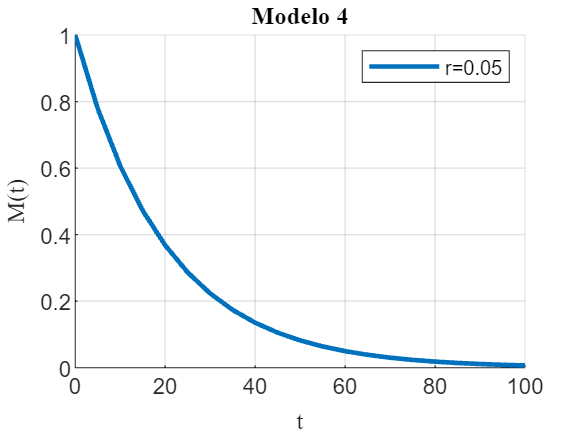

figure;
hold on;
for i = 1:n
    M_subs = subs(M, [r t0, M0], [r_values(i), ic_values(i,1), ic_values(i,2)]);
    
    % Evaluar la solución en los valores de tiempo dados
    M_values = subs(M_subs, t, t_values);
    
    % Graficar la solución
    plot(t_values, M_values, 'LineWidth', 2, 'DisplayName', ['r=' num2str(r_values(i))]);
end
xlabel('t','FontName','latex');
ylabel('M(t)','FontName','latex');
title('Modelo 4','FontName','latex');
legend('show');
grid on;
hold off;

Observamos que a mayor es la proporción del gasto, menos cantidad de dinero se ahorra (para r = 0.8, los valores de M(t) son menores).

#### 4. Estudio de estabilidad

Estabilidad es ocurre cuando $\frac{\textrm{dM}}{\textrm{dt}}=0$; sustituyo:

 
$$\begin{array}{l}
0=-r\cdot M\\
M=0
\end{array}$$


syms M r
eq =-r*M == 0;
solve(eq,M)

$$ans = 0$$

Observamos en la gráfica que efectivamente se estabiliza, cuando $M=0$ en cualquiera de los casos. El estado estacionario o de equilibrio es **trivial**.

### Por circuito en Simulink

**Limpieza del entorno de trabajo**

clear     % limpieza del espacio de trabajo
clc       % limpieza de línea de comando
close all % cerrar todas las figuras

#### Configuración usuario 

Se muestran los ajustes elejidos por el usuario aplicables a cualquier modelo de simulación discreta. 

Configuración del solver

solver = struct();
solver.type = "Variable-Step";
solver.name = "ode45";
solver.start = 0;
solver.stop = 15;
solver.step = 1;

Nombre del modelo

model_name = "modelo3";

Condiciones iniciales y constantes del modelo:

k_values =  [0,0,0];
r_values = [-0.4, -0.1, -0.8];
ic_values = [0 1; 0 1; 0 1];
t_values = 0:5:100;
[m, n] = size(k_values);

sim_config, función que simula el modelo de nombre model_name para una configuración de solver almacenada en el struct solver. Recibe como argumentos el nombre del modelo y un struct con la configuración del solver.

sim_data = sim_config(model_name, solver); % End of file definition

De sim_data se extrae la información de la simulación gracias a bloques output.

Obtenemos un data set con las señales del campo yout

signals = sim_data.yout;
M1 = signals{1}.Values.Data

M1 =    -0.4000   -0.1000   -0.8000
   -0.3618   -0.0975   -0.6544
   -0.3209   -0.0946   -0.5147
   -0.2846   -0.0918   -0.4049
   -0.2524   -0.0891   -0.3185
   -0.2239   -0.0865   -0.2506
   -0.1985   -0.0839   -0.1971
   -0.1761   -0.0815   -0.1550
   -0.1562   -0.0790   -0.1220
   -0.1385   -0.0767   -0.0959


M = signals{2}.Values.Data

M =     1.0000    1.0000    1.0000
    0.9044    0.9752    0.8180
    0.8021    0.9464    0.6434
    0.7114    0.9184    0.5061
    0.6310    0.8913    0.3981
    0.5596    0.8649    0.3132
    0.4963    0.8394    0.2464
    0.4402    0.8146    0.1938
    0.3904    0.7905    0.1524
    0.3463    0.7671    0.1199


signal_time = signals{1}.Values.Time;

#### Gráfica 1

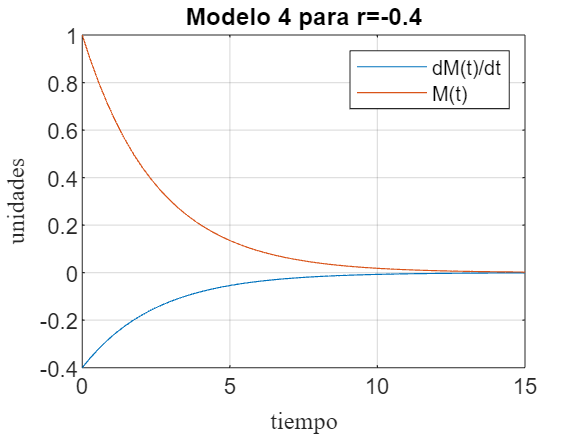

[m, n] = size(M1);
for i =1:n
    figure
    plot(signal_time, M1(:,i))
    hold on
    plot(signal_time, M(:,i))
    grid on
    xlabel("tiempo","FontName","latex");
    ylabel("unidades","FontName","latex");
    title(['Modelo 4 para r=' num2str(r_values(i))]);
    legend('dM(t)/dt','M(t)');
    hold off
end 

#### Gráfica 2

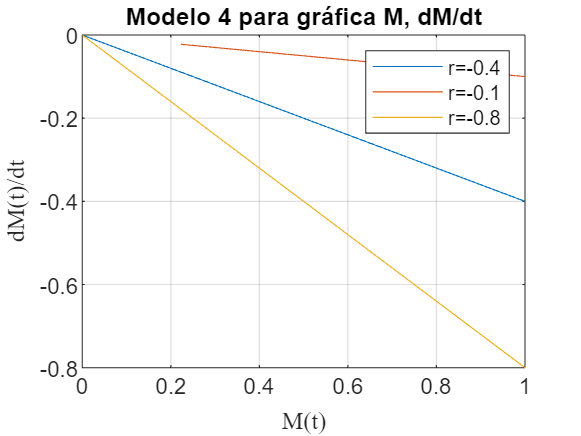

[m, n] = size(M1);
figure
for i =1:n
    plot(M(:,i), M1(:,i), 'DisplayName', ['r=' num2str(r_values(i))])
    grid on
    xlabel("M(t)","FontName","latex");
    ylabel("dM(t)/dt","FontName","latex");
    title('Modelo 4 para gráfica M, dM/dt');
    hold on
end 
legend('show')

### ***Funciones disponibles para todas las secciones***

MATLAB permite utilizar la última sección de un livescript para definir funciones globales.

**Decorador de la función sim de MATLAB**

Esta función ejecuta la función sim, tras establecer los parámetros del solver. Recibe como argumentos el nombre del modelo y un struct con la configuración del solver.

function sim_data = sim_config(model_name, solver)

Carga del modelo con load_system

load_system(model_name)
% open_system(model_name) will also open it

Configuración con set_param

% Set solver parameters
set_param(model_name, ...
    SolverType  = solver.type, ...
    SolverName  = solver.name, ...
    StartTime   = string(solver.start),...
    StopTime    = string(solver.stop), ...
    FixedStep   = string(solver.step) ...
    )
% More model parameters can be retrieved with:
% model_data = get_param(model_name, "ObjectParameters")
% Access blocks params with "model_name/block_name"

Simulación del modelo con sim

sim_data = sim(model_name);
% SimulationMode="normal" by default
end

Se utiliza el bloque Out1 para cada señal.